# Transformada de Fourier

**Materia**

Señales y Sistemas

**Elaborado por:**

Gael Jovani López García - 1191699

Diego Bejarano Bedolla - 1191498

**Maestro**

Jorgue Ibarra Esquer

## Introducción

La transformada Discreta de Fourier es una herramienta matemática utilizada para descomponer una señal en sus componentes de frecuencia. Es especialmente útil para analizar señaes periódicas o no periódicas en el dominio de la frecuencia, permitiendo estudiar la magnitud y la fase de sus componentes espectrales

Matemáticamente, la Transformada Discreta de Fourier de una señal x[n] co N muestras se representa con:

$X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack *e^{-j*\frac{2*\pi }{N}*k*n}$, $k=0,1,\ldotp \ldotp \ldotp N-1$

Donde:


$$\begin{array}{l}
x\left\lbrack n\right\rbrack :\textrm{Señal}\;\textrm{en}\;\textrm{el}\;\textrm{dominio}\;\textrm{del}\;\textrm{tiempo}\\
X\left\lbrack k\right\rbrack :\textrm{Espectro}\;\textrm{de}\;\textrm{frecuencias}\\
N:\textrm{Número}\;\textrm{de}\;\textrm{muestras}
\end{array}$$


Además la operación inversa, reconstruye la señal original:


$$x\left\lbrack n\right\rbrack =\frac{1}{N}*\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack *e^{j*\frac{2\pi }{N}*k*n}$$


## Aplicaciones de la transformada Discreta de Fourier

- Procesamiento de imagenes

- Procesamiento de vídeos, sonidos

- Detección de ruido(detonaciones alrededor del mundo)

- Análisis de sistemas eléctricos

## Algoritmo de transformada rápida de Fourier(pequeño contexto)

La transformada rápida de Fourier por sus siglas FFT en inglés es la respuesta a la problematica a la transformada de Fourier, que indispensablemente era fundamental en el procesamiento de señales pero sus cálculos eran lentos ya que normalmente una señal de N puntos requería realizar N^2 operaciones, esto significaba que a medida que el tamaño de la señal aumentaba, el tiempo de cálculo crece de forma cuadrática

**Revolución de la transformada rápida de Fourier**

Gracias a James Cooley y John Tukey, fue desarrollado esta optimización del cálculo de DFT mediante el enfoque de "divide y vencerás", lo que redujo significativamente la complejidad computacional.

La complejidad reducida pasó de $O\left(N^2 \right)\;$a $O\left(N*\log *N\right)$

**Comparación de eficiencia**

**Proposito de este reporte**

El proposito de este reporte es aplicar de la transformada rapida de fourier para aplicar un filtro a una imagén y ver impacto claro de este concepto a una aplicación. Además, antes de aplicar FFT se mostrarán algunos ejemplos a continuación:

## Transformada Rápida de Fourier (FFT)

La "Transformación rápida de Fourier", FFT para abreviar, es un importante método de medición en la tecnología de medición de audio y acústica. Descompone una señal en sus componentes espectrales individuales y así proporciona información sobre su composición. Los FFT se utilizan para el análisis de errores, el control de calidad y la monitorización de las condiciones de las máquinas o sistemas.


$$X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack *e^{-j\frac{2\pi }{N}\textrm{kn}}$$


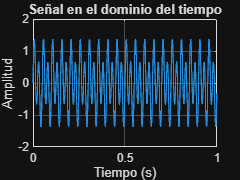

% Ejemplo FFT
fs = 1000;
t = 0:1/fs:1-1/fs;     % Vector de tiempo
f1 = 40; 
f2 = 20; 
amplitud1 = 1;       
amplitud2 = 0.5;       

% Crear la señal
senal = amplitud1 * sin(2 * pi * f1 * t) + amplitud2 * sin(2 * pi * f2 * t);

% Calcular la FFT de la señal
fft_resultado = fft(senal);
n = length(senal);    
frecuencias = (0:n-1)*(fs/n); 

% Tomar solo la mitad del espectro (frecuencias positivas)
magnitude = abs(fft_resultado/n);  % Normalizar el espectro
magnitude = magnitude(1:floor(n/2));
frecuencias = frecuencias(1:floor(n/2));

figure(1);
plot(t, senal);
title('Señal en el dominio del tiempo');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

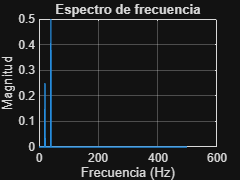


figure(2);
plot(frecuencias, magnitude);
title('Espectro de frecuencia');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
grid on;

## **Funcion fftshift**

La función fftshift es una herramienta que se usa en combinación con la Transformada Rápida de Fourier para centrar el espectro de frecuencia alrededor de cero. Esta funcion cambia el orden de los elementos de la FFT de tal forma que las frecuencias negativas se coloquen en el centro del espectro y las frecuencias positivas se ubiquen a los lados. Esto hace que el espectro sea más fácil de interpretar, especialmente cuando se está analizando una señal en el dominio de la frecuencia.

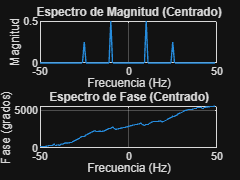

% Ejemplo FFT 
fs = 100;                         
t = 0:1/fs:1-1/fs;                 
x = sin(2*pi*10*t) + 0.5*sin(2*pi*25*t);
X = fft(x);                        
n = length(X);                     
f_shifted = (-n/2:n/2-1)*(fs/n);   

X_shifted = fftshift(X);           
magnitude_shifted = abs(X_shifted)/n; 
phase_shifted = unwrap(angle(X_shifted));

figure(1);
subplot(2,1,1);
plot(f_shifted, magnitude_shifted);
title('Espectro de magnitud (centrado)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
grid on;

subplot(2,1,2);
plot(f_shifted, phase_shifted*180/pi);
title('Espectro de fase (centrado)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');
grid on;

## **Transformada Rápida Inversa de Fourier (IFFT)**

La **Transformada Rápida Inversa de Fourier **(**IFFT**) es el proceso matemático que convierte una señal del dominio de **la **frecuencia de vuelta al dominio del tiempo. En otras palabras, es la operación inversa de la FFT (Transformada Rápida de Fourier), que convierte una señal del dominio del tiempo al dominio de la frecuencia.


$$X\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{n=0}^{N-1} X\left\lbrack k\right\rbrack *e^{j\frac{2\pi }{N}\textrm{kn}}$$


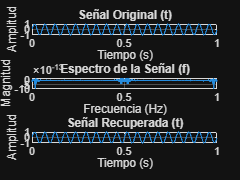

% Ejemplo IFFT
fs = 1000;              
t = 0:1/fs:1-1/fs;       

f = 18; % Frecuencia de la señal
senal_original = sin(2*pi*f*t);  

% Realizar la FFT de la señal
X = fft(senal_original);

% Aplicar la IFFT para recuperar la señal original
senal_recuperada = ifft(X);

figure;
subplot(3,1,1);
plot(t, senal_original);
title('Señal original (t)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(3,1,2);
plot(t, real(X));  
title('Espectro de la señal (f)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
grid on;

subplot(3,1,3);
plot(t, real(senal_recuperada));
title('Señal recuperada (t)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

## Caso de estudio

En este caso se presentará una imagen como se mencionó, donde se le aplicará un filtro, para visualizar más a detalle la transformada rápida de Fourier

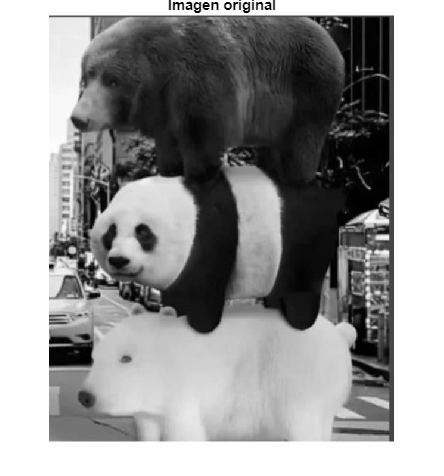

clear;

% Ejemplo imagen
figure;
img = imread('imagenSyS.jfif');
img_gray = rgb2gray(img);
imshow(img_gray);
title('Imagen original');

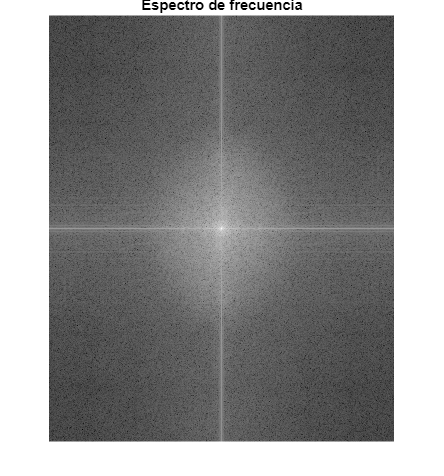


F = fft2(img_gray); % Aplicar la Transformada de Fourier bidimensional

% Desplazar el cero de la frecuencia al centro del espectro
F_shifted = fftshift(F);

% Calcular el espectro de magnitud
magnitude_spectrum = log(1 + abs(F_shifted));

% Calcular el espectro de fase
phase_spectrum = angle(F_shifted);

% Visualizar el espectro de frecuencia
figure;
imshow(magnitude_spectrum, []);
title('Espectro de frecuencia');

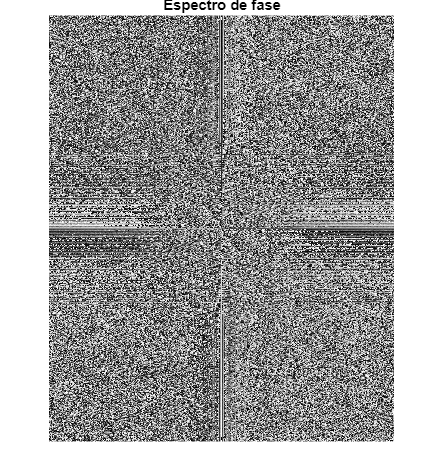


% Visualizar el espectro de fase
figure;
imshow(phase_spectrum, []);
title('Espectro de fase');

## **Espectro de frecuencia**

En tal caso, al momento de "descomponer" la imagen y obtener el espectro de frecuencia, obtenemos lo que es la intensidad o ampliud de las frecuencias presentes en la señal, es un valor positivo y real que muestra que tan fuerte está presente cada componente de frecuencia,en imagenes como es el caso, suele destacar las frecuencias bajas(información suave como tonos) o altas (detalles como bordes o ruido)

## **Espectro de fase**

Representa el desplazamiento angular de los componentes sinusoidales en el dominio de la frecuencia, donde se pueden tener valores positivos o negativos, y su rango típico es de -$\pi$ a $\pi$

Además el espectro de fase no tiene un claro efecto en una señal, pero es indispensable para la reconstrucción de la señal original

## Procesamiento de frecuencia

Una maravilla de la transformada de fourier, es que con ella además de comprimir una imagen, podemos por así decirlo "modificarla" donde tomamos los componentes bajos de la frecuencia, y las modificamos para hacerlas altas y por así decirlo cambiar el contorno de la imagen

A continuación:

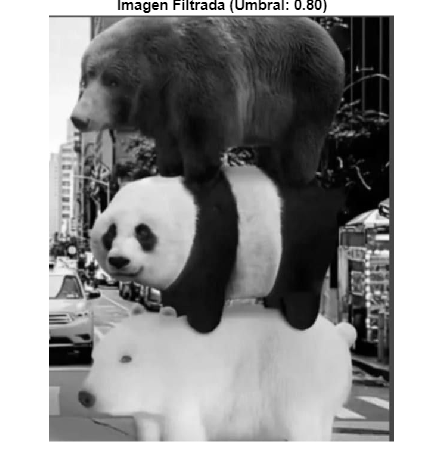

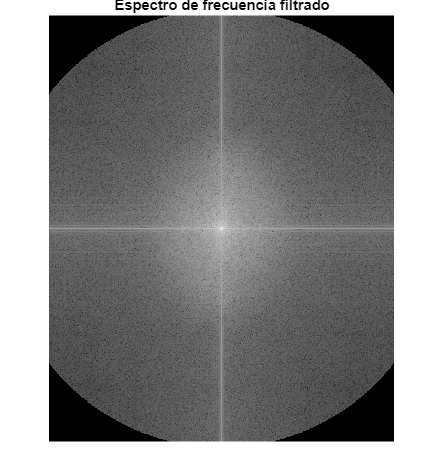

% Establecer un valor fijo para el umbral
threshold = 0.8; % Umbral fijo que puedes cambiar manualmente

% Función para aplicar el filtro pasa bajo
apply_filter(threshold, F_shifted);


% Función de procesamiento
function apply_filter(threshold, F_shifted)
    % Crear un filtro pasa bajo en el dominio de la frecuencia
    [rows, cols] = size(F_shifted);
    [X, Y] = meshgrid(1:cols, 1:rows);
    centerX = ceil(cols / 2);
    centerY = ceil(rows / 2);
    distance = sqrt((X - centerX).^2 + (Y - centerY).^2);
    
    % Crear el filtro basado en el umbral
    filter = double(distance <= threshold * max(distance(:)));
    
    % Aplicar el filtro pasa bajo en el dominio de la frecuencia
    F_filtered = F_shifted .* filter;
    
    % Regresar la imagen al dominio espacial usando la transformada inversa
    img_filtered = ifft2(ifftshift(F_filtered));
    img_filtered = real(img_filtered);
    
    % Actualizar la imagen filtrada en la subgráfica
    figure;
    imshow(img_filtered, []);
    title(['Imagen Filtrada (Umbral: ', num2str(threshold, '%.2f'), ')']);
    
    % Calcular el espectro de frecuencia filtrado
    figure;
    MAGNITUDE_SPECTRUM_filtered = log(1 + abs(F_filtered));
    imshow(MAGNITUDE_SPECTRUM_filtered, []);
    title('Espectro de frecuencia filtrado');
end


## Transformada inversa rápida de Fourier al caso de estudio

Si bien, ya se mencionó, es posible reconstruir una imagen comprimida por la trasnformada de Fourier simplememente aplicando su inversa que como ya se mostró:


$$X\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{n=0}^{N-1} X\left\lbrack k\right\rbrack *e^{j\frac{2\pi }{N}\textrm{kn}}$$


Anteriormente, se habló de que es la transformada inversa rápida de Fourier y se mostró la fórmula para poder aplicarla a señales y obtener esta transformada inversa rápida de Fourier, a continuación se muestra como aplicar esta ecuación a una aplicación más acercada a la que se usaría comúnmente, veremos como aplicarla a una imagen.

A continuación:

clear;

%% Espectro de frecuencia de la imagen
% Leer y convertir a escala de grises
img = imread('imagenSyS.jfif');
img_gray = rgb2gray(img);


A continuación se hacen las transformadas y operaciones necesarias para obtener el resultado óptimo de la transformada inversa rápida de Fourier, para realizar las operaciones se utilizan las funciones de matlab encargadas de hacer todos los cálculos necesarios.

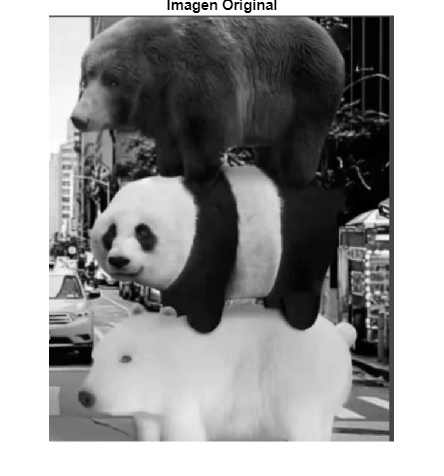

% Transformada de Fourier bidimensional
F = fft2(img_gray);

% Desplazar el espectro para centrar las bajas frecuencias
F_shifted = fftshift(F);

% Calcular el espectro de magnitud (logarítmico para visualización)
magnitude_spectrum = log(1 + abs(F_shifted));

% Mostrar la imagen original
figure;
imshow(img_gray, []);
title('Imagen original');

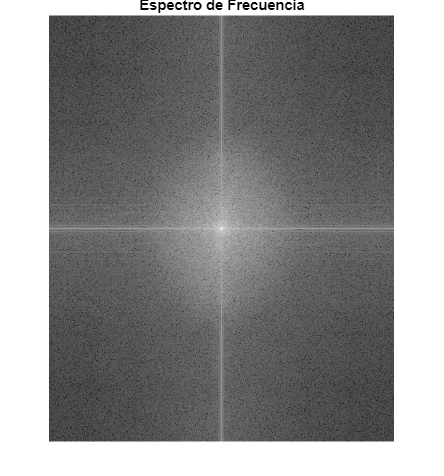


% Mostrar el espectro de magnitud
figure;
imshow(magnitude_spectrum, []);
title('Espectro de Frecuencia');

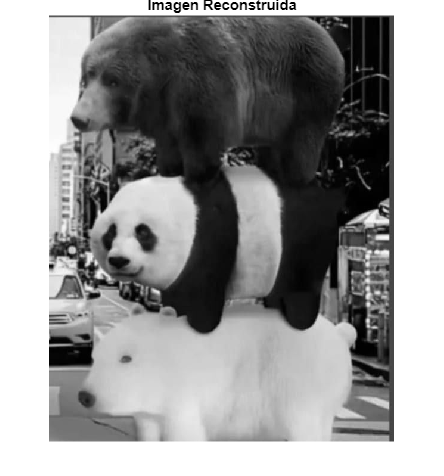


% Transformada inversa de Fourier para regresar al dominio espacial
F_inverse = ifft2(F);
img_reconstructed = real(F_inverse); % Tomar solo la parte real

% Mostrar la imagen reconstruida
figure;
imshow(img_reconstructed, []);
title('Imagen reconstruida');

Por último se muestran las fases de las imágenes, conforme se fueron aplicando las operaciones, primero tenemos a la imagen original sin ningún tipo de operación más que la conversión a escala de grises. Después tenemos el espectro completo de la imagen, y por último tenemos la reconstrucción de la imagen, a partir del espectro de frecuencia de la imagen. 

## Segunda imagen (Aplicar transformada rápida de Fourier e inversa)

Aquí tenemos otro ejemplo con otra imagen para observa como se comporta con diferentes imagenes.

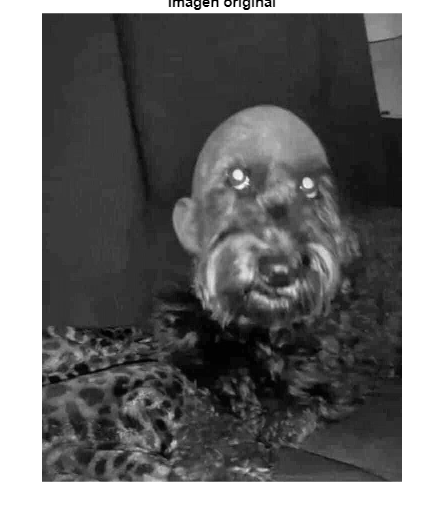

clear;

%% Espectro de frecuencia de la imagen
% Leer y convertir a escala de grises
img = imread('perro.jfif');
img_gray = rgb2gray(img);

% Transformada de Fourier bidimensional
F = fft2(img_gray);

% Desplazar el espectro para centrar las bajas frecuencias
F_shifted = fftshift(F);

% Calcular el espectro de magnitud (logarítmico para visualización)
magnitude_spectrum = log(1 + abs(F_shifted));

% Mostrar la imagen original
figure;
imshow(img_gray, []);
title('Imagen original');

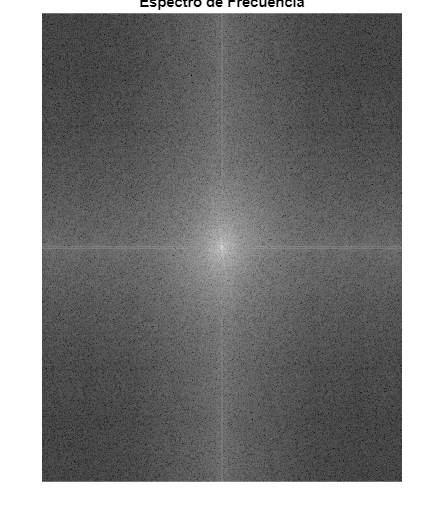


% Mostrar el espectro de magnitud
figure;
imshow(magnitude_spectrum, []);
title('Espectro de Frecuencia');

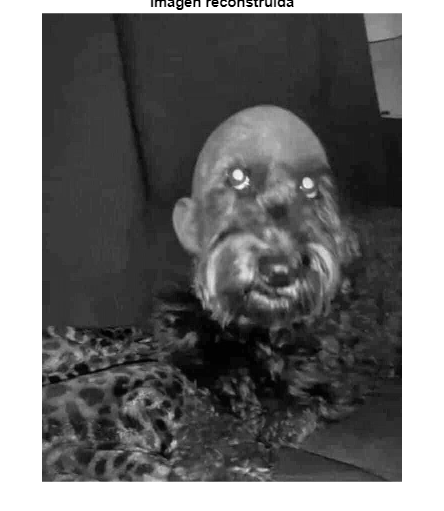


% Transformada inversa de Fourier para regresar al dominio espacial
F_inverse = ifft2(F);
img_reconstructed = real(F_inverse); % Tomar solo la parte real

% Mostrar la imagen reconstruida
figure;
imshow(img_reconstructed, []);
title('Imagen reconstruida');

## Tercera imagen (aplicar transformada rápida de Fourier e inversa)

Por último tenemos esta imagen en la cual se puede observar un cambio en el espectro de frecuencia.

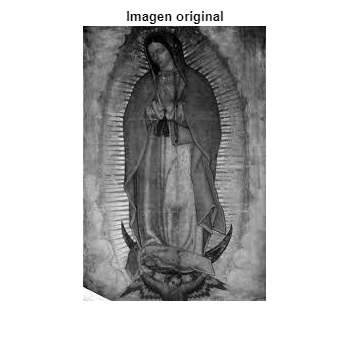

clear;

%% Espectro de frecuencia de la imagen
% Leer y convertir a escala de grises
img = imread('guadalupe.jfif');
img_gray = rgb2gray(img);

% Transformada de Fourier bidimensional
F = fft2(img_gray);

% Desplazar el espectro para centrar las bajas frecuencias
F_shifted = fftshift(F);

% Calcular el espectro de magnitud (logarítmico para visualización)
magnitude_spectrum = log(1 + abs(F_shifted));

% Mostrar la imagen original
figure;
imshow(img_gray, []);
title('Imagen original');

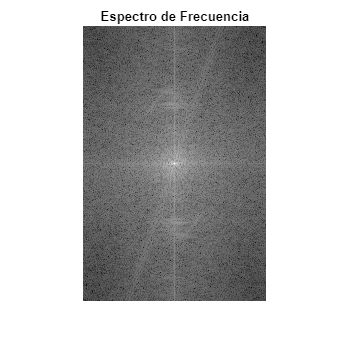


% Mostrar el espectro de magnitud
figure;
imshow(magnitude_spectrum, []);
title('Espectro de Frecuencia');

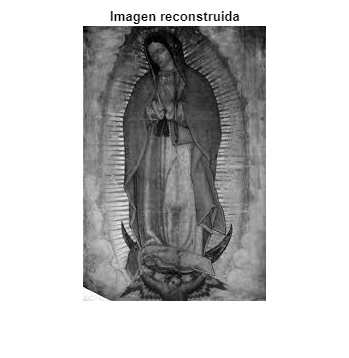


% Transformada inversa de Fourier para regresar al dominio espacial
F_inverse = ifft2(F);
img_reconstructed = real(F_inverse); % Tomar solo la parte real

% Mostrar la imagen reconstruida
figure;
imshow(img_reconstructed, []);
title('Imagen reconstruida');

## Conclusiones de imagenes

Al utilizar la transformada inversa de Fourier nos dimos cuenta de que estas ecuaciones son muy útiles al igual que muy impresionantes, el poder descomponer una imagen en frecuencias y luego poder volver a recomponer la imagen original con solo las frecuencias es algo muy impresionante. El realizarlo en este proyecto para entender como es que funciona tanto en la teoría como el poder aplicarlo en algún software como lo es matlab, es fundamental para entender realmente como es que se aplica este tipo de ecuaciones en la industria y en la vida cotidiana. Estos ejemplos que pusimos de imágenes es básicamente lo que haría una página de compresión de imágenes, el comprimir una imagen desasiéndose de las frecuencias no tan importantes para que no ocupe tanto espacio es algo que se realiza mucho en la vida diaria.

Con las imagenes pudimos observar las distintas etapas por las que pasa la imagen durante la realización de la transformada de Fourier, primero tuvimos la imagen original para tener una referencia de que es lo que esta sucediendo en cada operación aplicada a la imagen, luego mostramos la imagen una vez aplicda la transformada donde pudimos ver el espectro de la imagen original y por útlimo volvimos a obtener la imagen origianl a partir del espectro de la imagen original. 

## Análisis de resultados

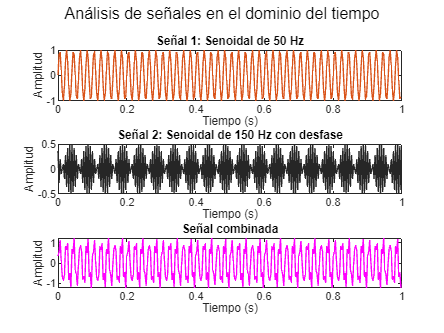

fs =320; % Frecuancia de muestreo

t = 0:1/fs:1-1/fs; % Vector de tiempo (1 segundo)
f1 = 50; % Frecuencia de la primera señal 
f2 = 150; % Frecuencia de la segunda señal 

% Generar señales iniciales
signal1 = sin(2*pi*f1*t); 
signal2 = 0.5*sin(2*pi*f2*t + pi/4); 

% Señal combinada para análisis adicional
signal_combined = signal1 + signal2;

% Procesamiento en el dominio de la frecuencia
fft_signal1 = fft(signal1);
fft_signal2 = fft(signal2);
fft_combined = fft(signal_combined);

% Crear filtro (ejemplo: pasa bajos)
cutoff = 100; 
filter_freq = zeros(size(t));
filter_freq(1:cutoff) = 1;
filter_freq(end-cutoff+1:end) = 1;

% Aplicar filtro en el dominio de la frecuencia
filtered_fft_combined = fft_combined .* filter_freq;
filtered_signal_combined = ifft(filtered_fft_combined, 'symmetric');

% Gráficas en el dominio del tiempo
figure;
sgtitle('Análisis de señales en el dominio del tiempo');

subplot(3, 1, 1);
plot(t, signal1, 'Color', [0.851 0.325 0.098]); 
title('Señal 1: Senoidal de 50 Hz');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(3, 1, 2);
plot(t, signal2, 'Color', [0.149 0.149 0.149]);
title('Señal 2: Senoidal de 150 Hz con desfase');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(3, 1, 3);
plot(t, signal_combined, 'Color', [1 0 1]);
title('Señal combinada');
xlabel('Tiempo (s)');
ylabel('Amplitud');

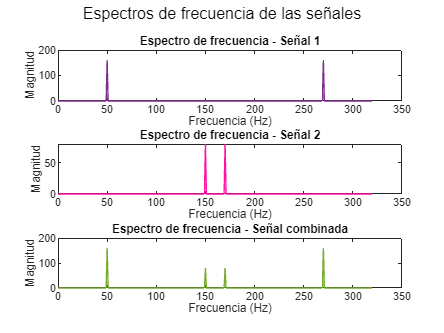


% Gráficas en el dominio de la frecuencia
freq_axis = (0:length(fft_signal1)-1)*(fs/length(fft_signal1));

figure;
sgtitle('Espectros de frecuencia de las señales');

subplot(3, 1, 1);
plot(freq_axis, abs(fft_signal1), 'Color', [0.494 0.184 0.557]);
title('Espectro de frecuencia - Señal 1');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

subplot(3, 1, 2);
plot(freq_axis, abs(fft_signal2), 'Color', [1.000 0.075 0.651]);
title('Espectro de frecuencia - Señal 2');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

subplot(3, 1, 3);
plot(freq_axis, abs(fft_combined), 'Color', [0.467 0.675 0.188]);
title('Espectro de frecuencia - Señal combinada');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

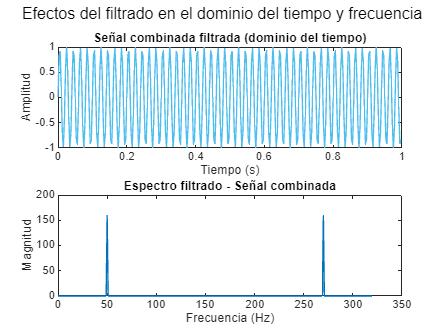


% Gráficas tras procesamiento en el dominio de la frecuencia
figure;
sgtitle('Efectos del filtrado en el dominio del tiempo y frecuencia');

subplot(2, 1, 1);
plot(t, filtered_signal_combined, 'Color', [0.302 0.745 0.933]);
title('Señal combinada filtrada (dominio del tiempo)');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(2, 1, 2);
plot(freq_axis, abs(filtered_fft_combined), 'Color', [0.000 0.447 0.741]);
title('Espectro filtrado - Señal combinada');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

En este experimento, trabajamos con dos señales sinusoidales: una de 50 Hz y otra de 150 Hz, que se combinaron para analizar cómo se comportan juntas en los dominios del tiempo y la frecuencia. Usamos la transformada de Fourier para ver sus componentes de frecuencia, encontrando picos claros en 50 Hz y 150 Hz. Luego aplicamos un filtro pasa bajos con corte en 100 Hz, lo que dejó solo la señal de 50 Hz al eliminar las frecuencias altas. Además, ajustamos la frecuencia de muestreo (fsf_sfs�) para observar cómo afecta el análisis: si es baja, aparece aliasing y se distorsionan los resultados, mientras que si es alta, todo se ve más claro. Al final, este ejercicio mostró cómo el filtrado y la frecuencia de muestreo son clave para procesar señales y entender sus componentes.

## Conclusión

**Gael Jovani López García**

Aunque la transformada de Fourier puede ser no muy conocida, es verdad que es fundamental en la informática, donde esta se utiliza en la compresión de imágenes y sonidos, que su uso es muy extenso en la ingeniería. Además,  permite analizar señales en el dominio de la frecuencia, lo que facilita identificar patrones, eliminar ruidos o incluso modificar ciertos componentes de una señal para mejorar su calidad. Su aplicación no se limita solo a imágenes y audio; también se usa en comunicaciones digitales, procesamiento de radar, reconocimiento de voz y muchos otros campos. La transformada de Fourier es, sin duda, una herramienta versátil que ha transformado la manera en que interactuamos con la información en el mundo digital.

**Diego Bejarano Bedolla**

La transformada de Fourier es una herramienta esencial en la sociedad actual, con aplicaciones fundamentales en internet y diversas industrias, donde se ha convertido en un estándar. Durante este proyecto, se llevaron a cabo distintas pruebas para explorar y demostrar el funcionamiento de estas ecuaciones. Utilizando las funciones integradas de matlab, se simplificó su implementación, permitiendo visualizar aplicaciones prácticas y graficar resultados que evidencian su utilidad y versatilidad en el análisis de señales.

## Referencias

FFT. (s. f.). Recuperado de [https://www.nti-audio.com/es/servicio/conocimientos/transformacion-rapida-de-fourier-fft](https://www.nti-audio.com/es/servicio/conocimientos/transformacion-rapida-de-fourier-fft)

Carina. (s. f.). TRANSFORMADA DE FOURIER. Recuperado de [http://carina.fcaglp.unlp.edu.ar/algebralineal/fourier.pdf](http://carina.fcaglp.unlp.edu.ar/algebralineal/fourier.pdf)